imp = cc.*pp;
scanobj = tscan;

sz1 = size(imp);
sz2 = size(scanobj);

f1 = sz2(1)/sz1(1);
f2 = sz2(2)/sz1(2);


xg = 1:sz1(1);
yg = 1:sz1(2);
F = griddedInterpolant({xg,yg},double(imp));

xq = (0:5/6:sz1(1))';
yq = (0:5/6:sz1(2))';
vq = (F({xq,yq}));
imshow(vq)

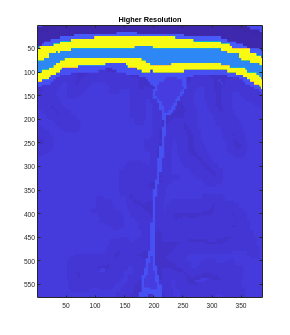

imagesc(vq);
title('Higher Resolution')